% === Parse durations per subject from Sub2.docx ===
textData = extractFileText('SubAll.docx');
lines = splitlines(textData);

% Storage
subjNames = {};
durPerSub = {};
curSubIdx = 0;

for k = 1:numel(lines)
    line = strtrim(lines{k});
    if isempty(line), continue; end

    % Detect subject header (e.g., "sub8:" or "Sub 34")
    s = regexp(line, '^\s*([sS]ub\s*\d+)\s*:?', 'tokens', 'once');
    if ~isempty(s)
        name = regexprep(lower(s{1}), '\s+', '');
        idx = find(strcmp(subjNames, name), 1);
        if isempty(idx)
            subjNames{end+1} = name; %#ok<SAGROW>
            durPerSub{end+1} = []; %#ok<SAGROW>
            curSubIdx = numel(subjNames);
        else
            curSubIdx = idx;
        end
        continue;
    end

    % Extract "length=####"
    t = regexp(line, 'length\s*=\s*(\d+)', 'tokens', 'once');
    if ~isempty(t)
        val = str2double(t{1});
        if curSubIdx == 0
            subjNames{end+1} = 'unknown'; %#ok<SAGROW>
            durPerSub{end+1} = []; %#ok<SAGROW>
            curSubIdx = numel(subjNames);
        end
        durPerSub{curSubIdx}(end+1) = val; %#ok<SAGROW>
    end
end

fprintf('Parsed %d subjects.\n', numel(subjNames));

Parsed 87 subjects.


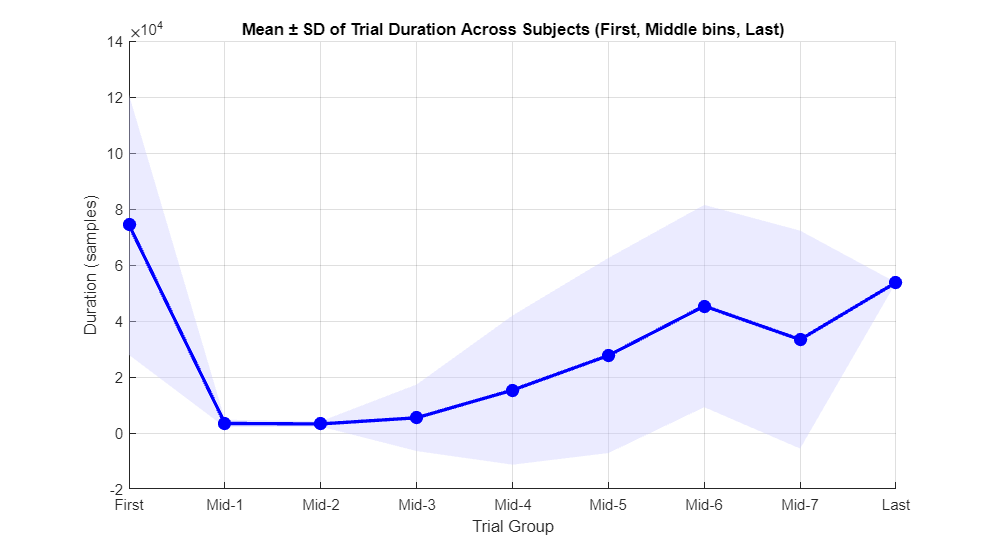


% === Divide trials: first (solo), middle (bins of 5), last (solo) ===
groupData = {}; % cell array of trial duration groups

for i = 1:numel(durPerSub)
    dur = durPerSub{i};
    n = numel(dur);
    if n < 2, continue; end

    % First trial
    if numel(groupData) < 1
        groupData{1} = [];
    end
    groupData{1}(end+1) = dur(1);

    % Middle trials
    mids = dur(2:end-1);
    nMid = numel(mids);
    nBins = ceil(nMid / 5);

    for b = 1:nBins
        idxStart = (b-1)*5 + 1;
        idxEnd = min(b*5, nMid);
        midChunk = mids(idxStart:idxEnd);
        if numel(groupData) < (b+1)
            groupData{b+1} = [];
        end
        groupData{b+1} = [groupData{b+1}, mean(midChunk)];
    end

    % Last trial
    lastIdx = nBins + 2;
    if numel(groupData) < lastIdx
        groupData{lastIdx} = [];
    end
    groupData{lastIdx}(end+1) = dur(end);
end

% === Compute mean and SD for each group ===
nGroups = numel(groupData);
groupMean = nan(1, nGroups);
groupSD   = nan(1, nGroups);

for g = 1:nGroups
    groupMean(g) = mean(groupData{g});
    groupSD(g)   = std(groupData{g});
end

% === Plot ===
figure('Name','Mean Trial Duration (First, Middles, Last)','NumberTitle','off','Position',[100 100 900 500]);
hold on;

x = 1:nGroups;
fill([x fliplr(x)], [groupMean+groupSD fliplr(groupMean-groupSD)], ...
    [0.8 0.8 1], 'EdgeColor','none', 'FaceAlpha', 0.4);
plot(x, groupMean, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');

xlabel('Trial Group');
ylabel('Duration (samples)');
title('Mean ± SD of Trial Duration Across Subjects (First, Middle bins, Last)');
grid on;

% Label x-axis
xticks(1:nGroups);
labels = ["First", strcat("Mid-", string(1:nGroups-2)), "Last"];
xticklabels(labels);

hold off;


fprintf('Groups: %s\n', strjoin(labels, ', '));

Groups: First, Mid-1, Mid-2, Mid-3, Mid-4, Mid-5, Mid-6, Mid-7, Last
